# Trajectory Planner for Lunar Lander

## Initial Data

tf = 20 %s

tf = 20

qi = 0 %m - valore integratore per y_0

qi = 0

qf = 200 %m

qf = 200

dotqc = 8*(qf-qi)/100 %m/s

dotqc = 16

## Compute $t_c$ and $\ddot{q_c}$

tc = tf - (qf - qi)/dotqc

tc = 7.5000


ddotqc = dotqc/tc

ddotqc = 2.1333

## Planner for $y$ trajectory

syms t

#### Tratto per $0\leq t \leq t_c$

q1 = qi + 0.5 * ddotqc * t^2;

#### Tratto per $t_c< t \leq (t_f - t_c)
$

q2 = qi + ddotqc*tc*(t-tc/2);

#### Tratto per $ (t_f - t_c)< t \leq t_f
$

q3 = qi + ddotqc*tc*(tf-tc-tc/2) + dotqc*(t-(tf-tc))-0.5*ddotqc*(t-(tf-tc))^2;

## Combine the 3 function computed

qt = piecewise(0<=t<=tc, q1, tc<t<=(tf-tc), q2, (tf-tc)<t<=tf, q3, t>tf, qf)

$$qt = \left\{ \begin{array}{cl} \frac{16\,t^{2}}{15} & \text{ if }t\in \left[0,\frac{15}{2}\right]\\ 16\,t-60 & \text{ if }t\in \left(\frac{15}{2},\frac{25}{2}\right]\\ 16\,t-\frac{16\,{\left(t-\frac{25}{2}\right)}^{2}}{15}-60 & \text{ if }t\in \left(\frac{25}{2},20\right]\\ 200 & \text{ if }20<t \end{array}\right.$$

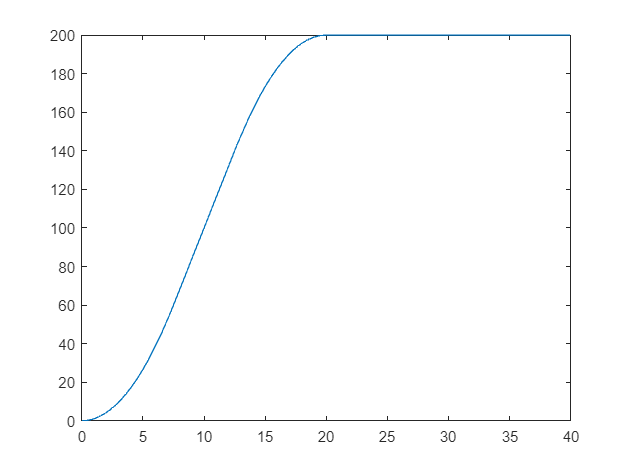

figure(1)
fplot(qt, [0, 2*tf])

## Planner for $v_y$ trajectory

dotq1 = ddotqc*t;
dotq2 = dotqc;
dotq3 = dotqc-ddotqc*(t-(tf-tc));

dotqt = piecewise(0<=t<=tc, dotq1, tc<t<=(tf-tc), dotq2, (tf-tc)<t<=tf, dotq3, t>tf, 0)

$$dotqt = \left\{ \begin{array}{cl} \frac{32\,t}{15} & \text{ if }t\in \left[0,\frac{15}{2}\right]\\ 16 & \text{ if }t\in \left(\frac{15}{2},\frac{25}{2}\right]\\ \frac{128}{3}-\frac{32\,t}{15} & \text{ if }t\in \left(\frac{25}{2},20\right]\\ 0 & \text{ if }20<t \end{array}\right.$$

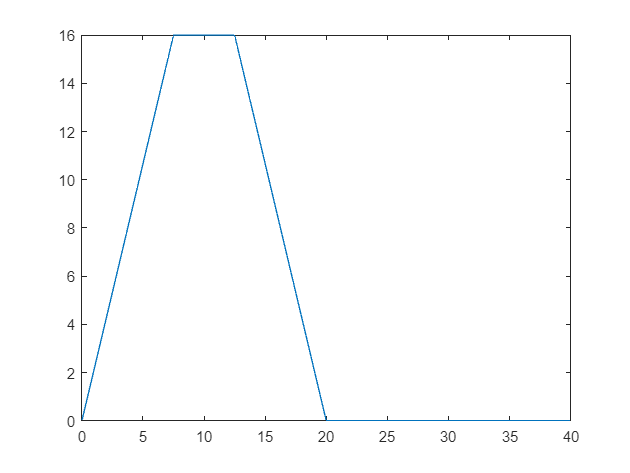

figure(2)
fplot(dotqt, [0, 2*tf])

## Planner for $a_y$ trajectory

ddotq1 = ddotqc;
ddotq2 = 0;
ddotq3 = -ddotqc;
ddotqt = piecewise(0<=t<=tc, ddotq1, tc<t<=(tf-tc), ddotq2, (tf-tc)<t<=tf, ddotq3, t>tf, 0)

$$ddotqt = \left\{ \begin{array}{cl} \frac{32}{15} & \text{ if }t\in \left[0,\frac{15}{2}\right]\\ 0 & \text{ if }t\in \left(\frac{15}{2},\frac{25}{2}\right]\\ -\frac{32}{15} & \text{ if }t\in \left(\frac{25}{2},20\right]\\ 0 & \text{ if }20<t \end{array}\right.$$

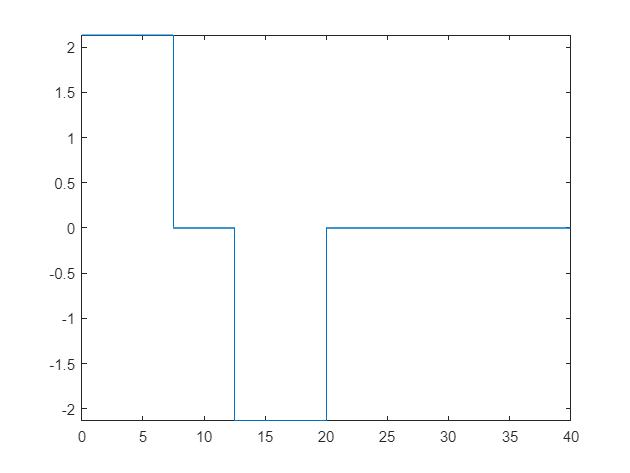

figure(3)
fplot(ddotqt, [0, 2*tf])